f1 = @(x) (6*x(:,1)-2).^2.*sin(12*x(:,2)-4);%.*sin(24*x-1);

x1 = lhsdesign(10,2);
y1 = f1(x1)+normrnd(0*x1(:,1),0*x1(:,1));


a = means.const(0);

l12 = -0.5

l12 = -0.5000

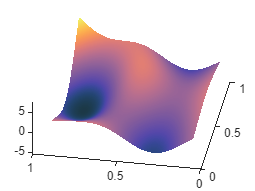


q = kernels.EQ_matrix(1,[2 l12 6]);%.periodic(2,5);

q.signn = eps;

Z = GP(a,q);

Z1 = Z.condition(x1,y1);

figure(1)
clf(1)
hold on
utils.plotSurf(Z1,2,1,'CI',false)
view(-80,60)
plot3(x1(:,1),x1(:,2),y1,'+','MarkerSize',18)